# LDC Model (Newtonian)

## House keeping

 %Tyson Cross       1239448
 %James Goodhead    1387118

clc; clear all;

## Code Run Choice 

PID_Outer = true;              % if false, Double loop and Outer PID controller is not added to system
Mechanical_Output = true;      % if false, mechanical output plots are not generated
Electrical_Output = true;      % if false, electrical outputs plots are generated
Temperature_Culc = true;              % if false, Temperature increase culculations are not performed

## Motor Newtonian Modelling

System_parameters;                                  %import motor physical paramemter 

%%% Newtonian Modelling of Motor (i.t.o displacement)
syms s t

Operation terminated by user during syms (line 229)


In LiveEditorEvaluationHelperEID459473392 (line 12)
syms s t

In matlab.internal.editor.evaluateRegions

In matlab.internal.editor.EvaluationOutputsService.evalRegions



num = 1;                                            % numerator of TF
s1 = l.*B + f.*R./(l.*B);                           % s term of 2nd order ODE
s2 = m.*(R./(l.*B));                                % s^2 term of 2nd order ODE
sden = s2.*(s.*s) + s1.*s ;                         % denominator of TF

% Modelling in terms of velocity
% sden = s2.*(s) + s1;
% sys = num./sden

sys = num./sden;                                    % TF as symbolic function
den = sym2poly(sden);
system = tf(num, den)                               % System as Transfer function


system =
 
            1
  ----------------------
  0.1333 s^2 + 0.06333 s
 
Continuous-time transfer function.



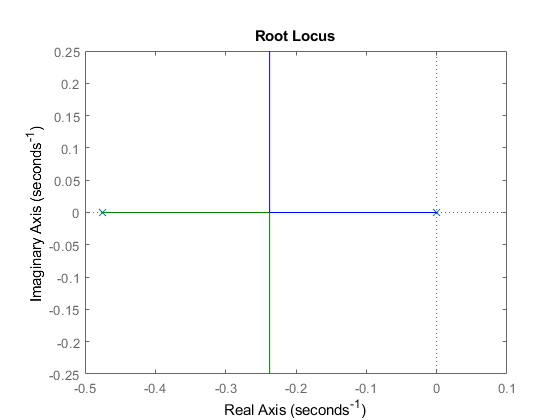

rlocus(system);                                     % Rootlocus of motor model

poles = eig(system);

% state space
[A1,B1,C1,D1] = ssdata(system);                 	% two state variables
rank_sys = rank(ctrb(A1,B1));
obs_sys = obsv(A1,C1);
rank_obs = rank(obs_sys);


## Symbolic Time Domain Solution


% % Solution to x (displacement in time domain)
% xt = ilaplace(X);                                	% inverse laplace

% % Solve for displacement as function of time symbolically
% syms x(t) y;
% Dx = diff(x);
% ode = m*diff(x,t,2) + ((l*l*B*B)/R + f)*diff(x,t) == l*B/R*y;
% cond1 = x(0) == 0;
% cond2 = Dx(0) == 0;
% conds = [cond1 cond2];
% xSol(t) = dsolve(ode,conds);
% xsol = simplify(xSol)

%%% Simulink: Control_system_simulation.slx


## PID Controler 1 modeling

% Outer loop
% Modelling of PID controller (Tuned)
if (PID_Outer)
 P = 0.898885625751871;                            	% proportional 
 I = 1.90243819948265;                           	% integral
 D = 0;                            	                % derivative
 N = 100;
PIDsystem_1 = P + I/s + D*(N/(1+(N/s)))            	% controller transfer function
clear P I D N;
else
    PIDsystem_1 = 1;
end

$$PIDsystem\_1 = \frac{2141954991571365}{1125899906842624\,s}+\frac{8096441938369643}{9007199254740992}$$

## PID Controler 2 modeling

%Inner loop
% Modelling of PID controller (Tuned)
 P = 0.159243539750473;                            	% proportional 
 I = 0.0209333117982786;                           	% integral
 D = 0.242558878110515;                            	% derivative
 N = 20.119;
PIDsystem_2 = P + I/s + D*(N/(1+(N/s)))            	% controller transfer function

$$PIDsystem\_2 = \frac{3016808166859453}{144115188075855872\,s}+\frac{175822045137393712673}{36028797018963968000\,\left(\frac{20119}{1000\,s}+1\right)}+\frac{717169146281389}{4503599627370496}$$

clear P I D N;

## System modeling (Frequencey Domain)

### Inner Loop 

% Model of entire system 
 Gs_inner = PIDsystem_2.*sys;                                 % Open loop (combined) transfer function
 Ts_inner = Gs_inner/(1+Gs_inner);                                         % Closed loop transfer function

 

###  Outer Loop 

 %Outer Loop
 if(PID_Outer)
 Gs_outer = PIDsystem_1.*Ts_inner;                            % Open loop transfer function (loop 2)
 Ts_outer = Gs_outer/(1+Gs_outer);                       % closed loop transer function
 Xs = 1/s;                                         	% Step input
 Ys = (Xs*Ts_outer)                                           % Output from closed loop transfer function
 else
      Xs = 1/s;                                         	% Step input
      Ys = (Xs*Ts_inner)                                        % Output from closed loop transfer function
 end

$$Ys = \begin{array}{l} \frac{\sigma_{2}}{s\,\left(\frac{2\,s^{2}}{15}+\frac{19\,s}{300}\right)\,\sigma_{1}\,\left(\frac{\sigma_{2}}{\left(\frac{2\,s^{2}}{15}+\frac{19\,s}{300}\right)\,\sigma_{1}}+1\right)}\\ \mathrm{where}\\ \sigma_{1}=\frac{\frac{3016808166859453}{144115188075855872\,s}+\frac{175822045137393712673}{36028797018963968000\,\left(\frac{20119}{1000\,s}+1\right)}+\frac{717169146281389}{4503599627370496}}{\frac{2\,s^{2}}{15}+\frac{19\,s}{300}}+1\\ \sigma_{2}=\left(\frac{2141954991571365}{1125899906842624\,s}+\frac{8096441938369643}{9007199254740992}\right)\,\left(\frac{3016808166859453}{144115188075855872\,s}+\frac{175822045137393712673}{36028797018963968000\,\left(\frac{20119}{1000\,s}+1\right)}+\frac{717169146281389}{4503599627370496}\right) \end{array}$$

## Mechanical Symbolic Outputs - Time Domain 

 if(Mechanical_Output)
 Distance = ilaplace(Ys);
 Velocity = diff(Distance);
 Acceleration = diff(Velocity);
 

####  Numerical Electrincal Outputs - Time Domain

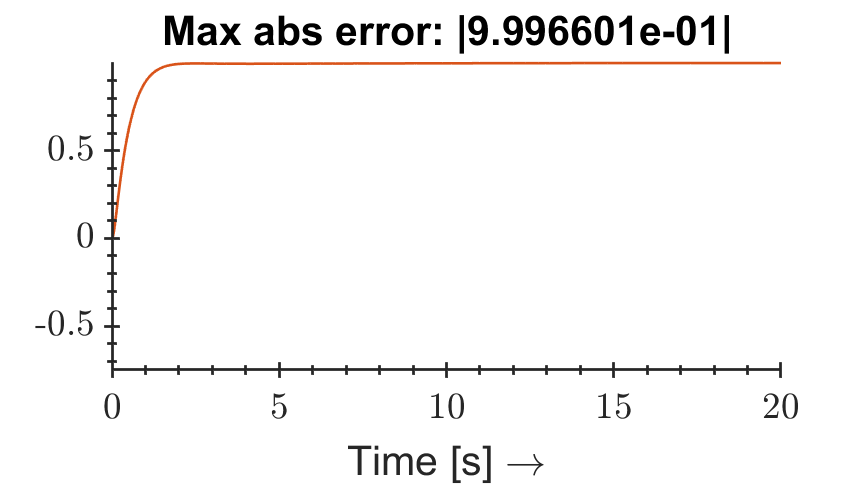

Undefined function or variable 'FillAxesPos'.

Error in plot_MechOutput (line 77)
axErrorClosed.Position = FillAxesPos(axErrorClosed,0.99);

 T = 0:0.01:20;  
 DistanceMatrix = double(subs(Distance,t,T));
 %VelocityMatrix = double(subs(Velocity,t,T));
 %AccelerationMatrix = double(subs(Acceleration,t,T));
 
 plot_MechOutput;
 else
 end

## Electrical Symbolic Outputs - Time Domain

 if(Electrical_Output)
 %Model of the Output of PID controler
 Xs = 1/s;
 controller2Effort = (Xs-Ys)*(PIDsystem_2);        	% Voltage applied to the motor
 MotorV = (ilaplace(controller2Effort,t));
 MotorC = MotorV./R;                               	% Current in the motor 
 MotorP = MotorC.*MotorV;                         	% instantanious Power
 MotorCE3 = double(int(abs(MotorP),t,0,4))
 %MotorCE = int(MotorP,t,0,t,'PrincipalValue',true); 	% Motor cumulative energy
 
 

#### Numerical Electrincal Outputs - Time Domain

 
 T = 0:0.01:20;                                   	% Time vector 
 MotorVmatrix = abs(double(subs(MotorV,t,T)));     	% voltage sampled at T
 MotorCmatrix = abs(MotorVmatrix./R);
 MotorPmatrix = MotorCmatrix.*MotorVmatrix;
 MotorCEmatrix = cumsum(MotorPmatrix.*0.001);
 else
 end

## Temperature Change Culculations 

if(Temperature_Culc)
 
    deltaT = MotorCE3/(0.75264*0.385)                         %0.385KJ/kgoC
    Rnew = R.*(1+0.00393*deltaT)                        %0.00303%/oC
 
% load the data simulation with stepped input voltage values
% load('cache/IO_data.mat');
% input = timeseries(cell2mat(in_data),t,'Name','input to blackbox');

else
end

